## Initialization

clc
clear all
close all
yalmip('clear');
% ------------- ------------------------------------------------%
echo on
% Autonomous Intersection - Yalmip Optimization
% Decentralized Framework
% Hybrid Vehicle
% MPC demo v 1.0
% with different weighting factor
% with varied step
% without turning 
% full version
% consider lateral consraint
% consider rear-end collision
% consider FIFO (when vehicles travel in opposite directions)
echo off

% W_total = [3.5,4,5,6,8,10,15,20,30,40,50,55,60,65,70,75,80,85,90,95,100,150,200,400,600];
% W_total = [1,5, 10,15,20,25,30,35,40,50,60,70,80,90,100,130,160,190,240,290,330,380,450,500,600,700,800,1000,5000,10000];
W_total = [1000,1500,2000,2500,2800,3200,3400,3800,4200,4600,5000,5300,5600,5900,6300,6600,6900,7200,7500,8000,8500,10000];
Energy_cost_total = zeros(1,length(W_total));
Travel_time_total = zeros(1,length(W_total));

for z = 1:length(W_total)
% ------------------------------------------------------------- %
% Model Parameters %
% ------------------------------------------------------------- %
W = W_total(z);      % weight in objective function
W_terminal = 1e-11;  % weight of terminal term

N_pre = 20; % predictive horizon
N_step = 2; % unit m, space domain

K = 20;      % number of total vehicles
K_sim = 20;

L = 150;     % distance from CZ to MZ
S = 10;      % length of MZ

disp('-------------------------------------------------------------')
disp('---------------------- MPC Settings -------------------------')
disp('-------------------------------------------------------------')
disp('Decentralized MPC for Autonomous Intersection Crossing')
disp(['Length of Control Zone (CZ),  L     = ',num2str(L),' m'])
disp(['Length of Merging Zone (MZ),  S     = ',num2str(S),' m'])
disp(['Total Vehicle Number,         N_veh = ',num2str(K_sim)])
disp(['Predictive Horizon Length,    N_pre = ',num2str(N_pre),' m'])
disp(['Sampling Time (Space Domain), ds    = ',num2str(N_step),' m'])
disp(['Weighting Factor Value,       W     = ',num2str(W)])
disp('-------------------------------------------------------------')
disp('-------------------- Start Simulation -----------------------')
disp('-------------------------------------------------------------')
% ------------------------------------------------------------- %
g = 9.81;    % gravity      
m = 1200;    % vehicle mass
fr = 0.01;   % rolling resistance coefficient
fd = 0.47;   % air drag resistance coefficient
rho = 0.5;   % energy recovery factor
Tsigma = 0.0;% braking system responsse time
a_min = -6.5;% maximum deceleration
a_max = 1.5; % maximum acceleration
gr = 3.5;    % transmission ratio
rw = 0.3;    % radius of vehicle wheels

% loading vehicle data
desired_arrivalrate = 5000; % 1500 400 5000
load('initial_20_1000.mat');
t0 = t0*3000/desired_arrivalrate;
t0 = t0 + 1;

% linearization on state E over v, v = a1*E + b1 
a1 = 8.5034e-05;
b1 = 4.9000;

% intersection settings
s0 = 0;                     % initial distance
sf_entry = L;               % intermediate distance (entry MZ)
sf_exit = L+S;              % terminal distance (leave MZ)

% terminal speed
v_final = 10;
E_final = 0.5*v_final^2*m;

% speed constraints
vmin = 0.1;  % min speed
vmax = 15;   % max speed
Emin = 0.5*vmin^2*m;              
Emax = 0.5*vmax^2*m;

% time constraints
tmin = 0;
tmax = 20000;

% torque control limits
Tm_min = -300;    % min driving force          
Tm_max = 300;    % max driving force

%NEW PARAMETERS
%fuel
m_f0 = 0.061; % initial fuel mass
alpha_f0 = 0.059; %  coefficient of power transformation

%voltage
Voc = 300; % constant open circuit voltage
Voc2 = 90000; %power 2
Q_max = 5*3600; % battery capacity
R_b = 0.2056; %  internal resistance;
SoC_final_max = 0.7; % maximum final SoC value
SoC_final_min = 0.5; % minimum final SoC value
SoC_final = 0.65;
SoC_max = 0.8; % maixmum SoC value
SoC_min = 0.2; % minimum SoC value
SoC0 = 0.65;
%approximate
a_SoC = -0.0007;

%power
P_ps_max = 70000;
P_ss_min = -15000;
P_ss_max = 30000;

%% model discretization
N_total = sf_exit/N_step; % total steps of each vehicle
n_MZ = (sf_exit-sf_entry)/N_step; % total steps in MZ of each vehicle
n_CZ = sf_entry/N_step; % total steps in CZ of each vehicle
N = N_pre/N_step; % predictive steps

-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 1000


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 1500


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 2000


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 2500


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 2800


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 3200


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 3400


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 3800


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 4200


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 4600


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 5000


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 5300


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 5600


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 5900


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 6300


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 6600


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 6900


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 7200


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 7500


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 8000


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 8500


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


-------------------------------------------------------------


---------------------- MPC Settings -------------------------


-------------------------------------------------------------


Decentralized MPC for Autonomous Intersection Crossing


Length of Control Zone (CZ),  L     = 150 m


Length of Merging Zone (MZ),  S     = 10 m


Total Vehicle Number,         N_veh = 20


Predictive Horizon Length,    N_pre = 20 m


Sampling Time (Space Domain), ds    = 2 m


Weighting Factor Value,       W     = 10000


-------------------------------------------------------------


-------------------- Start Simulation -----------------------


-------------------------------------------------------------


## MPC controller

% space domain, t_i time, E_i kinetic energy
% state variables
X_i = sdpvar(repmat(4,1,N+1),ones(1,N+1));
t_i = sdpvar(repmat(1,1,N+1),ones(1,N+1)); %#ok<*REPMAT>
E_i = sdpvar(repmat(1,1,N+1),ones(1,N+1));
SoC_i = sdpvar(repmat(1,1,N+1),ones(1,N+1));
mf_i = sdpvar(repmat(1,1,N+1),ones(1,N+1));

% control variables
U_i = sdpvar(repmat(4,1,N),ones(1,N));
F_ps_i = sdpvar(repmat(1,1,N),ones(1,N)); 
F_ss_i = sdpvar(repmat(1,1,N),ones(1,N)); 
Fb_i = sdpvar(repmat(1,1,N),ones(1,N)); 
% convex dummy input
dummy_i = sdpvar(repmat(1,1,N),ones(1,N)); 

% define terminal speed constraint index, only need when current position
% adding predictive horizon exceeds the entire control length 
n_terminal_v = sdpvar(1,N+1);

% define lateral end time and ego vehicle position, only need when lateral
% constraint shall active in the MZ
n_MZ_lateral = sdpvar(1,N+1);
v_MZ_lateral_end_time = sdpvar(1);

% define rear-end time and speed, only need if two vehicles travel in the
% same direction
n_rear_end = sdpvar(1,N+1);
t_rear_end = sdpvar(1,N+1);
E_rear_end = sdpvar(1,N+1);

% definne FIFO policy, only need if opposite vehicle coming
n_FIFO_entry = sdpvar(1,N+1);
n_FIFO_exit = sdpvar(1,N+1);
t_FIFO_front = sdpvar(1,N+1);

% new added constraints
n_terminal_SoC = sdpvar(1,N+1);

constraints = [];
objective = 0;

for k = 1:N % sum of state, constraint, objective function
    
    % define objective function, sum of energy and time costs
    objective = objective + (m_f0*dummy_i{k}+alpha_f0*F_ps_i{k}) + W*(dummy_i{k});
    
    % assign time and kinetic energy states
    constraints = [constraints, t_i{k} == X_i{k}(1)];
    constraints = [constraints, E_i{k} == X_i{k}(2)];
    constraints = [constraints, SoC_i{k} == X_i{k}(3)];
    constraints = [constraints, mf_i{k} == X_i{k}(4)];
   
    % differential equations
    constraints = [constraints, t_i{k+1} == t_i{k} + N_step * dummy_i{k}];
    constraints = [constraints, E_i{k+1} == E_i{k} + N_step * (F_ss_i{k} + F_ps_i{k} + Fb_i{k}-fr*m*g-2*fd*E_i{k}/m)];
    constraints = [constraints, mf_i{k+1} == mf_i{k} + N_step * (m_f0 * dummy_i{k} + alpha_f0 * F_ps_i{k})];
    constraints = [constraints, SoC_i{k+1} == SoC_i{k} + N_step * (a_SoC * F_ss_i{k})];
    
    % note: cpower is used to create a conic model of rational powers in Yalmip
    constraints = [constraints, dummy_i{k} - cpower(2*E_i{k}/m,-0.5) >= 0];
    
    % states limits
    constraints = [constraints, SoC_min <= SoC_i{k} <= SoC_max];
    constraints = [constraints, tmin <= t_i{k} <= tmax];
    constraints = [constraints, Emin <= E_i{k} <= Emax];
    constraints = [constraints, 0 <= dummy_i{k}];
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    constraints = [constraints, Fb_i{k} <= 0];
    constraints = [constraints, 0 <= F_ps_i{k} <= P_ps_max*dummy_i{k}];
    constraints = [constraints, P_ss_min*dummy_i{k} <= F_ss_i{k} <= P_ss_max*dummy_i{k}];
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    
    % define terminal speed constraint index, only need when current position
    % adding predictive horizon exceeds the entire control length 
    constraints = [constraints, n_terminal_v(k)*E_i{k} == n_terminal_v(k)*E_final];
    
    % define terminal SoC constraint index, only need when current position
    % adding predictive horizon exceeds the entire control length 
    constraints = [constraints, n_terminal_SoC(k)*SoC_i{k} == n_terminal_SoC(k)*0.65];
     
    % define lateral constraint if needed 
    constraints = [constraints, n_MZ_lateral(k)*t_i{k} >= n_MZ_lateral(k)*v_MZ_lateral_end_time];
    
    % define rear-end constraint if needed
    constraints = [constraints, n_rear_end(k)*t_i{k}-t_rear_end(k) >= ...
                    (a1*(n_rear_end(k)*E_i{k})+n_rear_end(k)*b1 - cpower(2*E_rear_end(k)/m,0.5))./(-a_min)];
    
    % define FIFO policy of the entry of the MZ if needed
    constraints = [constraints, n_FIFO_entry(k)*t_i{k} >= n_FIFO_entry(k)*t_FIFO_front(k)];
    % define FIFO policy of the exit of the MZ if needed
    constraints = [constraints, n_FIFO_exit(k)*t_i{k} >= n_FIFO_exit(k)*t_FIFO_front(k)];            

end

% assign terminal states, time and kinetic energy
constraints = [constraints, t_i{N+1} == X_i{N+1}(1)];
constraints = [constraints, E_i{N+1} == X_i{N+1}(2)];
constraints = [constraints, SoC_i{N+1} == X_i{N+1}(3)];
constraints = [constraints, mf_i{N+1} == X_i{N+1}(4)];

constraints = [constraints, tmin <= t_i{N+1} <= tmax];
constraints = [constraints, Emin <= E_i{N+1} <= Emax];

% terminal cost on terminal speed within a horizon to ensure vehicle
% doesnot slow down to 0 velocity at the end of a horizon
objective = objective + W_terminal * (E_i{N+1} - E_final).^2 + W_terminal * (SoC_i{N+1} - 0.65).^2;

% terminal conditions   
% define terminal speed constraint index, only need when current position
% adding predictive horizon exceeds the entire control length 
constraints = [constraints,  n_terminal_v(N+1)*E_i{N+1} == n_terminal_v(N+1)*E_final];    

% define terminal SoC constraint index, only need when current position
% adding predictive horizon exceeds the entire control length 
constraints = [constraints, n_terminal_SoC(N+1)*SoC_i{N+1} == n_terminal_SoC(N+1)*0.65];    

% define lateral constraint if needed 
constraints = [constraints, n_MZ_lateral(N+1)*t_i{N+1} >= n_MZ_lateral(N+1)*v_MZ_lateral_end_time];

% define rear-end constraint if needed
constraints = [constraints, n_rear_end(N+1)*t_i{N+1}-t_rear_end(N+1) >= ...
                    (a1*(n_rear_end(N+1)*E_i{N+1})+n_rear_end(N+1)*b1 - cpower(2*E_rear_end(N+1)/m,0.5))./(-a_min)];

 % define FIFO policy of the entry of the MZ if needed
constraints = [constraints, n_FIFO_entry(N+1)*t_i{N+1} >= n_FIFO_entry(N+1)*t_FIFO_front(N+1)];
% define FIFO policy of the exit of the MZ if needed
constraints = [constraints, n_FIFO_exit(N+1)*t_i{N+1} >= n_FIFO_exit(N+1)*t_FIFO_front(N+1)];                

% controller output, control inputs and states within a horizon
solutions_out = {[F_ps_i{:}], [F_ss_i{:}], [Fb_i{:}], [dummy_i{:}], [t_i{:}], [E_i{:}], [SoC_i{:}], [mf_i{:}]};

ops = sdpsettings('solver','mosek','verbose',1,'debug',1); 
controller_decentralized = optimizer(constraints, objective,ops,...
    {X_i{1},n_terminal_v,... % terminal speed
    n_terminal_SoC,... % terminal SoC
    n_MZ_lateral,v_MZ_lateral_end_time,... % lateral constraint
    n_rear_end,t_rear_end,E_rear_end,... % rear-end constraint
    n_FIFO_entry,n_FIFO_exit,t_FIFO_front},... % FIFO policy
    solutions_out);

## intial settings for numerical example

%% intial settings for numerical example 
sim_time = N_total;
computation_time = zeros(1,K);

vehicle_direction = zeros(1,K);
% towards: 1 north, 2 west, 3 south, 4 east
vehicle_direction(indexp(seq_north)) = 1;
vehicle_direction(indexq(seq_west)) = 2;
vehicle_direction(indexp(seq_south)) = 3;
vehicle_direction(indexq(seq_east)) = 4;

constraint_activaion = zeros(3,K); % lateral, rear-end, FIFO
constraint_activaion(1,2:end) = seq;  % lateral active number
constraint_activaion(2,:) = 1;

FIFO_initial = zeros(1,K);
% direction_p = [0,diff(vehicle_direction(mod(vehicle_direction,2)==1))];
% direction_p(direction_p~=0) = 1;
% direction_q = [0,diff(vehicle_direction(mod(vehicle_direction,2)~=1))];
% direction_q(direction_q~=0) = 1;
% FIFO_initial(indexp) = direction_p;
% FIFO_initial(indexq) = direction_q;

FIFO_initial = [0,diff(vehicle_direction)];
FIFO_initial(FIFO_initial==0) = 1;
FIFO_initial_1 = mod(FIFO_initial,2);
FIFO_initial = mod((FIFO_initial_1 + 1),2);

constraint_activaion(3,:) = FIFO_initial;

N_north = 0;
N_west = 0;
N_south = 0;
N_east = 0;

N_north_south = 0;
N_west_east = 0;

% total energy consumption and time cost
Jb = 0;
Jt = 0;

%%
for v_num = 1:K_sim
    
    % rear-end constraint initial settings & activation factor
    t_rear_end_front_predictive = zeros(N_total,N+1);
    E_rear_end_front_predictive = zeros(N_total,N+1);
    n_rear_end_predictive = ones(1,N+1);
    
    % first vehicle in every direction, no rear-end constraint
    if vehicle_direction(v_num) == 1 % north
        N_north = N_north + 1;
        if N_north == 1
            constraint_activaion(2,v_num) = 0;
        else
            % indexp(seq_north(N_north-1)) 
            t_rear_end_front_predictive = eval(['t_predictive_',num2str(indexp(seq_north(N_north-1))),';']); % 上一辆车的mpc数据
            E_rear_end_front_predictive = eval(['E_predictive_',num2str(indexp(seq_north(N_north-1))),';']);
        end
    elseif vehicle_direction(v_num) == 2 % west
        N_west = N_west + 1;
        if N_west == 1
            constraint_activaion(2,v_num) = 0;
        else
            t_rear_end_front_predictive = eval(['t_predictive_',num2str(indexq(seq_west(N_west-1))),';']);
            E_rear_end_front_predictive = eval(['E_predictive_',num2str(indexq(seq_west(N_west-1))),';']);
        end
    elseif vehicle_direction(v_num) == 3 % south
        N_south = N_south + 1;
        if N_south == 1
            constraint_activaion(2,v_num) = 0;
        else
            t_rear_end_front_predictive = eval(['t_predictive_',num2str(indexp(seq_south(N_south-1))),';']);
            E_rear_end_front_predictive = eval(['E_predictive_',num2str(indexp(seq_south(N_south-1))),';']);
        end
    else
        N_east = N_east + 1;
        if N_east == 1
            constraint_activaion(2,v_num) = 0; % east
        else
            t_rear_end_front_predictive = eval(['t_predictive_',num2str(indexq(seq_east(N_east-1))),';']);
            E_rear_end_front_predictive = eval(['E_predictive_',num2str(indexq(seq_east(N_east-1))),';']);
        end
    end

    % lateral constraint initial settings
    t_predictive_lateral = zeros(N_total,N+1);
    E_predictive_lateral = zeros(N_total,N+1);
    if constraint_activaion(1,v_num) == 1
        t_predictive_lateral = eval(['t_predictive_',num2str(v_num-1),';']);
        E_predictive_lateral = eval(['E_predictive_',num2str(v_num-1),';']);
    end
    
    % FIFO policy initial settings 
    % decide if the FIFO shall active
    t_FIFO_front_predictive = zeros(N_total,N+1);
    % FIFO policy of the opposite vehicle state
    N_north_south = N_north + N_south;
    N_west_east = N_west + N_east;
    if constraint_activaion(3,v_num) == 1
        if mod(vehicle_direction(v_num),2) == 1 % north-south
            t_FIFO_front_predictive = eval(['t_predictive_',num2str(indexp(N_north_south-1)),';']);
        else % west-east
            t_FIFO_front_predictive = eval(['t_predictive_',num2str(indexq(N_west_east-1)),';']);
        end
    end
    
% end

% for v_num = 1:K
    
    % actual states for vehicle i
    t_jihe_i = zeros(1,N_total+1);
    E_jihe_i = zeros(1,N_total+1);
    SoC_jihe_i = zeros(1,N_total+1);
    mf_jihe_i = zeros(1,N_total+1);
    x_0_i = zeros(4,N_total+1);

    % initial conditions
    t_x = t0(v_num);
    E_x = 0.5*m*v0(v_num)^2;
    SoC_x = SoC0;
    mf_x = 0;
    
    t_jihe_i(:,1) = t_x;
    E_jihe_i(:,1) = E_x;
    SoC_jihe_i(:,1) = SoC_x;
    mf_jihe_i(:,1) = mf_x;
    x_0_i(:,1) = [t_x;E_x;SoC_x;mf_x];

    
    % actual control actions
    F_ps_jihe_i = zeros(1,N_total);
    F_ss_jihe_i = zeros(1,N_total);
    Fb_jihe_i = zeros(1,N_total);
    dummy_jihe_i = zeros(1,N_total);
    
    % predictive states
    t_predictive_i = zeros(N_total,N+1);
    E_predictive_i = zeros(N_total,N+1);
    SoC_predictive_i = zeros(N_total,N+1);
    mf_predictive_i = zeros(N_total,N+1);
    
    % terminal speed, active factor
    n_terminal_extra = zeros(1,N+1);
    
    % terminal SoC
    SoC_terminal_extra = zeros(1,N+1);
    
    
    % display step
    fs={'\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bVechile #%d MPC step %d/160',...
        '\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bVechile #%d MPC step %d/160',...
        '\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bVechile #%d MPC step %d/160',...
        '\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bVechile #%d MPC step %d/160'};
    if v_num<10
        fprintf('Vechile #  MPC step  /160');
    else
        fprintf('Vechile #   MPC step  /160');
    end
    
    for i = 1:N_total    
        % decide - lateral constraint 
        v_lateral_terminal_time = 0;
        if constraint_activaion(1,v_num) == 1
            if (((i-1)+N)*N_step >= L) && ((i-1)*N_step <= L )% ego vehicle predictive horizon reaches the MZ and has not enter MZ
                % t_x % current time
                if t_x <= max(t_predictive_lateral(:,1)) % when vehicle #1 has not left MZ
                    time_check = (t_predictive_lateral(:,1) - t_x).^2; % find vehicle #1 time
                    [~,pointer] = min(time_check); % find vehicle #1 position (search start from 0 - 164 m)
                    v_lateral_terminal_pointer = (N_total)-(pointer-1)+1; % find vehicle #1 terminal time at time pointer
                    % when vehicle #1 has terminal time in the predictive horizon
                    if v_lateral_terminal_pointer <= (N+1) 
                        v_lateral_terminal_time = t_predictive_lateral(pointer,v_lateral_terminal_pointer);
                    % when vehicle #1 doesnot have terminal time in the predictive horizon
                    else 
                        pre_distance_exta =  (v_lateral_terminal_pointer - (N+1))*N_step; % distance for vehicle #1 at v_lateral_terminal_pointer to end of MZ
                        v_lateral_terminal_time = t_predictive_lateral(pointer,(N+1)) + ...
                            pre_distance_exta/(sqrt(2*E_predictive_lateral(pointer,N+1)/m)); % average speed between the end speed of this horizon and terminal settinng speed
                        % note E_predictive_1 pick N_pre index as the end index is
                        % minimum settinng speed since terminal speed constraint has
                        % not active for vehicle #1 
                    end
                end
            end
        end
        
        % decide if the lateral constraint shall active, find MZ position index
        n_MZ_extra = zeros(1,N+1);
        if constraint_activaion(1,v_num) == 1
            vehicle_predict_MZ = ((i-1) + N)*N_step;
            if vehicle_predict_MZ >= L && ((i-1)*N_step <= L) % ego vehicle has not enter the MZ
                extra_MZ = ((i-1) + N) - (L)/N_step;
                n_MZ_extra(end-extra_MZ) = 1;
            end
        end
        
        
        % decide FIFO activation factor
        n_FIFO_MZ_entry = zeros(1,N+1);
        n_FIFO_MZ_exit = zeros(1,N+1);
        if constraint_activaion(3,v_num) == 1
            vehicle_predict_FIFO = ((i-1) + N)*N_step;
            % entry of the MZ
            if vehicle_predict_FIFO >= L && ((i-1)*N_step <= (L))
                extra_FIFO_MZ_entry = ((i-1) + N) - (L)/N_step;
                n_FIFO_MZ_entry(end-extra_FIFO_MZ_entry) = 1;
            end
            % exit of the MZ
            if vehicle_predict_FIFO >= L+S 
                extra_FIFO_MZ_exit = ((i-1) + N) - (L+S)/N_step;
                n_FIFO_MZ_exit(end-extra_FIFO_MZ_exit) = 1;
            end
        end
        
        % decide if the terminal speed constraint should active
        vehicle_predict_end = ((i-1) + N)*N_step;
        if vehicle_predict_end >= L+S % terminal point (L+S) is included in predictive horizon
            extra = ((i-1) + N) - (L+S)/N_step;
            n_terminal_extra(end-extra) = 1;
        end
        
        %decide if the terminal SoC constraint should active
        if vehicle_predict_end >= L+S % terminal point (L+S) is included in predictive horizon
            extra = ((i-1) + N) - (L+S)/N_step;
            SoC_terminal_extra(end-extra) = 1;
        end
        
        % solve MPC
        % display step
%         disp(['Vehicle #',num2str(v_num),', MPC step ', num2str(i),'/',num2str(N_total)])
        fprintf(fs{1+(i*N_step>10)+(i*N_step>100)+(v_num>=10)},v_num,i*N_step);
        
        %
        t_sim0 = cputime;
        
        
        [solutions,diagnostics] = controller_decentralized{ x_0_i(:,i),n_terminal_extra,... % terminal speed
                                SoC_terminal_extra,...% terminal SoC
                                n_MZ_extra,v_lateral_terminal_time,... % lateral constrainnt
                                n_rear_end_predictive,t_rear_end_front_predictive(i,:),E_rear_end_front_predictive(i,:),... % rear-end constraint
                                n_FIFO_MZ_entry,n_FIFO_MZ_exit,t_FIFO_front_predictive(i,:)}; % FIFO policy
       
       
        computation_time_max(i,v_num) = N_step/(sqrt(2*E_x/m));
        computation_time(i,v_num) = cputime-t_sim0;
                            
                            
        F_ps_control_i = solutions{1};
        F_ss_control_i = solutions{2};
        Fb_control_i = solutions{3};
        dummy_control_i = solutions{4};
        % predictive state
        t_predictive_i(i,:) = solutions{5};
        E_predictive_i(i,:) = solutions{6};
        SoC_predictive_i(i,:) = solutions{7};
        mf_predictive_i(i,:) = solutions{8};
        
        if diagnostics == 1
            error('The problem is infeasible'); 
        end
                
        
        t_x = t_x + N_step * dummy_control_i(1);
        E_x = E_x + N_step * ((F_ps_control_i(1)+F_ss_control_i(1)) + Fb_control_i(1)-fr*m*g-2*fd*E_x/m);
        SoC_x = SoC_x + N_step * (a_SoC * F_ss_control_i(1));
        mf_x = mf_x + N_step * (m_f0 * dummy_control_i(1) + alpha_f0 * F_ps_control_i(1));
        
        x_0_i(:,i+1) = [t_x;E_x;SoC_x;mf_x];
        
        t_jihe_i(:,i+1) = t_x;
        E_jihe_i(:,i+1) = E_x;
        SoC_jihe_i(:,i+1) = SoC_x;
        mf_jihe_i(:,i+1) = mf_x;

        F_ps_jihe_i(:,i) = F_ps_control_i(1);
        F_ss_jihe_i(:,i) = F_ss_control_i(1);
        Fb_jihe_i(:,i) = Fb_control_i(1);
        dummy_jihe_i(:,i) = dummy_control_i(1);
        
    end
    
    % display step
    fprintf('\n');
    
    eval(['t_jihe_',num2str(v_num),'=','t_jihe_i;']);
    eval(['E_jihe_',num2str(v_num),'=','E_jihe_i;']);
    eval(['SoC_jihe_',num2str(v_num),'=','SoC_jihe_i;']);
    eval(['mf_jihe_',num2str(v_num),'=','mf_jihe_i;']);
    eval(['t_predictive_',num2str(v_num),'=','t_predictive_i;']);
    eval(['E_predictive_',num2str(v_num),'=','E_predictive_i;']);
    eval(['SoC_predictive_',num2str(v_num),'=','SoC_predictive_i;']);
    eval(['mf_predictive_',num2str(v_num),'=','mf_predictive_i;']);
    
    % total energy consumption and time cost
    Jb = Jb + mf_jihe_i(81)-m_f0;
    Jt = Jt + N_step*sum(dummy_jihe_i);
    
end

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160

Vechile #  MPC step  /160

Vechile #1 MPC step 160/160

Vechile #  MPC step  /160

Vechile #2 MPC step 160/160

Vechile #  MPC step  /160

Vechile #3 MPC step 160/160

Vechile #  MPC step  /160

Vechile #4 MPC step 160/160

Vechile #  MPC step  /160

Vechile #5 MPC step 160/160

Vechile #  MPC step  /160

Vechile #6 MPC step 160/160

Vechile #  MPC step  /160

Vechile #7 MPC step 160/160

Vechile #  MPC step  /160

Vechile #8 MPC step 160/160

Vechile #  MPC step  /160

Vechile #9 MPC step 160/160

Vechile #   MPC step  /160

Vechile #10 MPC step 160/160

Vechile #   MPC step  /160

Vechile #11 MPC step 160/160

Vechile #   MPC step  /160

Vechile #12 MPC step 160/160

Vechile #   MPC step  /160

Vechile #13 MPC step 160/160

Vechile #   MPC step  /160

Vechile #14 MPC step 160/160

Vechile #   MPC step  /160

Vechile #15 MPC step 160/160

Vechile #   MPC step  /160

Vechile #16 MPC step 160/160

Vechile #   MPC step  /160

Vechile #17 MPC step 160/160

Vechile #   MPC step  /160

Vechile #18 MPC step 160/160

Vechile #   MPC step  /160

Vechile #19 MPC step 160/160

Vechile #   MPC step  /160

Vechile #20 MPC step 160/160


%% display energy consumption and time cost
disp('-------------------------------------------------------------')

-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


disp('-------------------- Simulation Result ----------------------')

-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


-------------------- Simulation Result ----------------------


disp('-------------------------------------------------------------')

-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


-------------------------------------------------------------


disp(['Average Energy Cost: ', num2str(Jb/K_sim),' kJ'])

Average Energy Cost: 2866.3197 kJ


Average Energy Cost: 2776.7245 kJ


Average Energy Cost: 2699.0136 kJ


Average Energy Cost: 2630.7939 kJ


Average Energy Cost: 2655.5337 kJ


Average Energy Cost: 2645.739 kJ


Average Energy Cost: 2665.2583 kJ


Average Energy Cost: 2779.0725 kJ


Average Energy Cost: 2988.5625 kJ


Average Energy Cost: 3254.3952 kJ


Average Energy Cost: 3520.2273 kJ


Average Energy Cost: 3710.2331 kJ


Average Energy Cost: 3893.1442 kJ


Average Energy Cost: 4101.4346 kJ


Average Energy Cost: 4357.6448 kJ


Average Energy Cost: 4555.2194 kJ


Average Energy Cost: 4725.7036 kJ


Average Energy Cost: 4876.789 kJ


Average Energy Cost: 5047.9456 kJ


Average Energy Cost: 5300.5193 kJ


Average Energy Cost: 5568.8012 kJ


Average Energy Cost: 6329.9736 kJ



disp(['Average Travel Time: ', num2str(Jt/K_sim),' s'])

Average Travel Time: 21.5753 s


Average Travel Time: 19.4697 s


Average Travel Time: 18.0962 s


Average Travel Time: 17.1101 s


Average Travel Time: 16.6679 s


Average Travel Time: 16.0897 s


Average Travel Time: 15.8785 s


Average Travel Time: 15.4875 s


Average Travel Time: 15.0906 s


Average Travel Time: 14.6936 s


Average Travel Time: 14.3234 s


Average Travel Time: 14.0861 s


Average Travel Time: 13.8659 s


Average Travel Time: 13.6404 s


Average Travel Time: 13.3494 s


Average Travel Time: 13.1601 s


Average Travel Time: 13.0007 s


Average Travel Time: 12.8484 s


Average Travel Time: 12.6937 s


Average Travel Time: 12.4667 s


Average Travel Time: 12.2599 s


Average Travel Time: 11.73 s


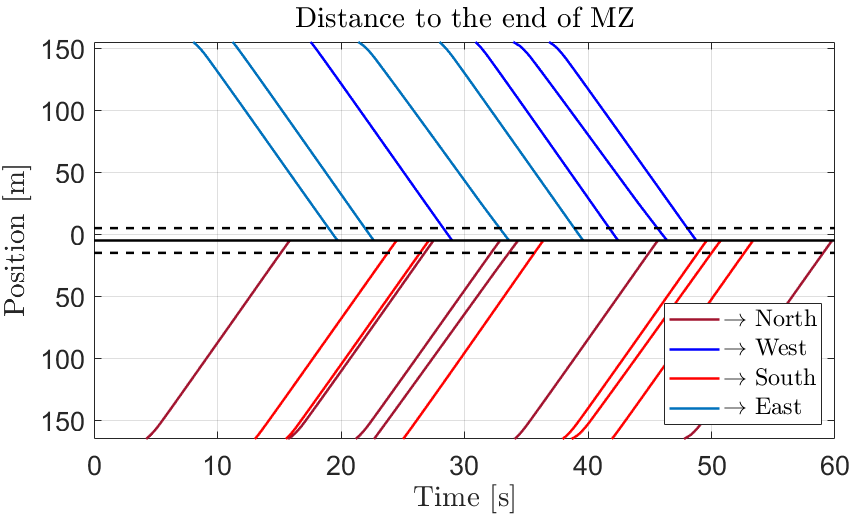

%%
Energy_cost_total(z) = Jb/K_sim;
Travel_time_total(z) = Jt/K_sim;

end

Decentralized_total = [Travel_time_total;Energy_cost_total];
% save Decetranlized_result_Np40 Decentralized_total
%%
% S-N 1, E-W 2, N-S 3, W-E 4
color_north = [0.6350, 0.0780, 0.1840];
color_south = [1, 0, 0];
color_east = [0, 0.4470, 0.7410];
color_west = [0, 0, 1];
color1 = [color_north;color_west;color_south;color_east];

%% Plot trajectories
s1 = 0;
s2 = 0;
s3 = 0;
s4 = 0;

figure(5)
x0=200;
y0=200;
width=510;
height=310;
set(gcf,'units','points','position',[x0,y0,width,height])
set(0,'defaultTextInterpreter','latex');
set(gca,'LooseInset',get(gca,'TightInset'))
t_sim_max = 0;
for draw_i = 1:K_sim
    if vehicle_direction(draw_i) == 1
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);
        s1 = plot(t_draw_i, cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)/max(cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)))*(L+S)),...
            'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5);
        hold on
    end
    
    if vehicle_direction(draw_i) == 2
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);
        s2 = plot(t_draw_i, 2*(L+S) - cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)/max(cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)))*(L+S)),...
            'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5);
        hold on
    end
    
    if vehicle_direction(draw_i) == 3
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);
        s3 = plot(t_draw_i, cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)/max(cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)))*(L+S)),...
            'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5);
        hold on
    end
    
    if vehicle_direction(draw_i) == 4
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);
        s4 = plot(t_draw_i, 2*(L+S) - cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)/max(cumtrapz(t_draw_i,sqrt(2*E_draw_i/m)))*(L+S)),...
            'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5);
        hold on
    end
    t_sim_max = ceil(max(t_draw_i));
end

plot(0:1:t_sim_max,ones(size(0:1:t_sim_max))*L,'k--','linewidth',1.5)
hold on
plot(0:1:t_sim_max,ones(size(0:1:t_sim_max))*(L+S),'k-','linewidth',1.5)
hold on
plot(0:1:t_sim_max,ones(size(0:1:t_sim_max))*(L+2*S),'k--','linewidth',1.5)
grid on

grid on
xlim([0,t_sim_max])
ylim([0,2*L+2*S])

yticks([15 65 115 165 215 265 315])
yticklabels({'150','100','50','0','50','100','150'})

xlabel('Time [s]')
ylabel('Position [m]')
set(gca,'fontsize',16)
title('Distance to the end of MZ')

legend_intersection = [s1;s2;s3;s4];
legend_label = {'$\rightarrow$ North','$\rightarrow$ West','$\rightarrow$ South','$\rightarrow$ East'};

if s1 == 0
    legend_intersection(1) = 0;
    legend_label{1} = '0';
end
if  s2 == 0
    legend_intersection(2) = 0;
    legend_label{2} = '0';
end
if s3 == 0
    legend_intersection(3) = 0;
    legend_label{3} = '0';
end
if s4 == 0
    legend_intersection(4) = 0;
    legend_label{4} = '0';
end
legend_intersection(legend_intersection==0) = [];

logic_legend = find(ismember(legend_label, '0'));
legend_label(logic_legend) = [];

legend(legend_intersection,legend_label,'interpreter','latex','location','southeast')



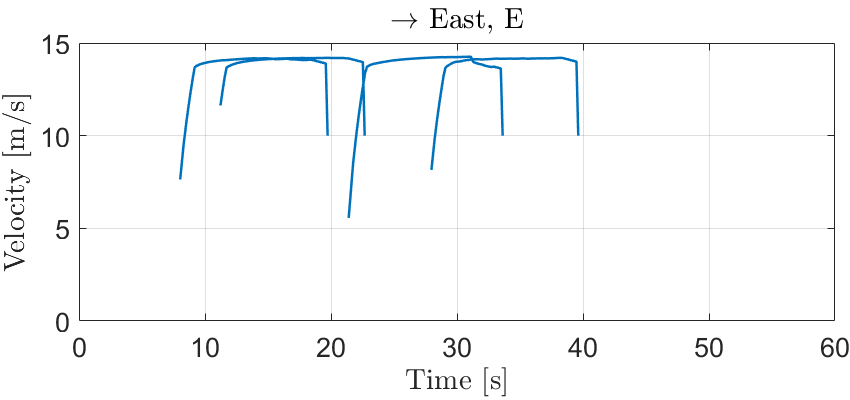

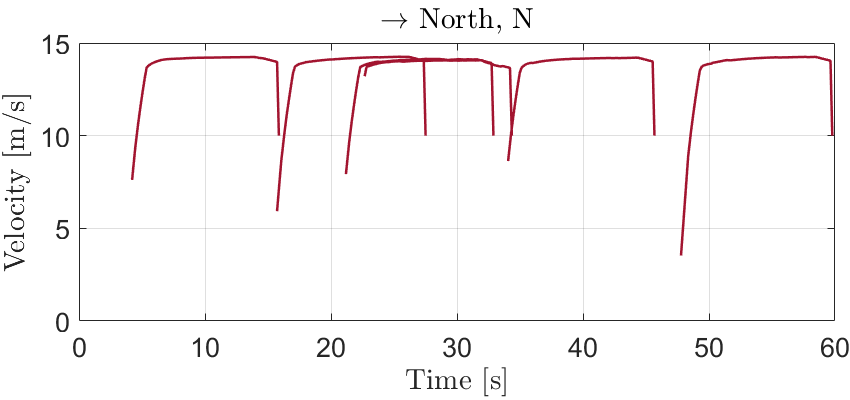

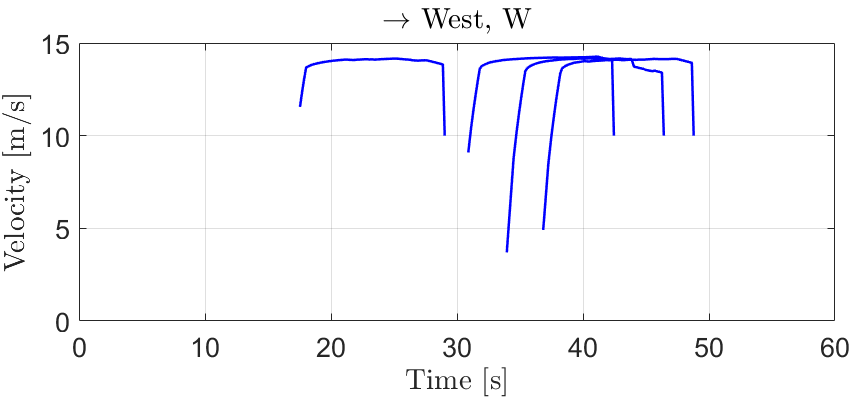

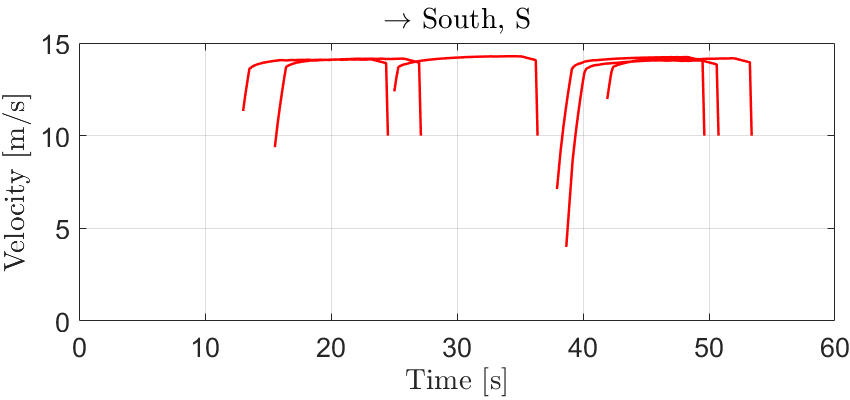


%% Plot Speed
for draw_i = 1:K_sim
    t_draw_i = [];
    E_draw_i = [];
    
    figure(1)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 1
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);        
        plot(t_draw_i,sqrt(2*E_draw_i/m),'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,vmax])
    grid on
    xlabel('Time [s]')
    ylabel('Velocity [m/s]')
    set(gca,'fontsize',16)
    title('$\rightarrow$ North, N','interpreter','latex')
    
    
    figure(2)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 2
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);
        plot(t_draw_i,sqrt(2*E_draw_i/m),'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,vmax])
    grid on
    xlabel('Time [s]')
    ylabel('Velocity [m/s]')
    set(gca,'fontsize',16)
    title('$\rightarrow$ West, W','interpreter','latex')
    
    figure(3)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 3
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);
        plot(t_draw_i,sqrt(2*E_draw_i/m),'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,vmax])
    grid on
    xlabel('Time [s]')
    ylabel('Velocity [m/s]')
    set(gca,'fontsize',16)
    title('$\rightarrow$ South, S','interpreter','latex')
    
      
    figure(4)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 4
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        E_draw_i = eval(['E_jihe_',num2str(draw_i),';']);
        plot(t_draw_i,sqrt(2*E_draw_i/m),'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,vmax])
    grid on
    xlabel('Time [s]')
    ylabel('Velocity [m/s]')
    set(gca,'fontsize',16)
    title('$\rightarrow$ East, E','interpreter','latex')
    
end

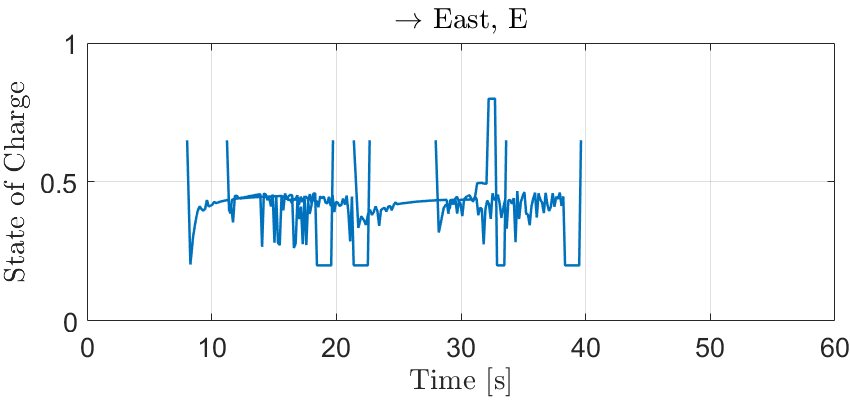

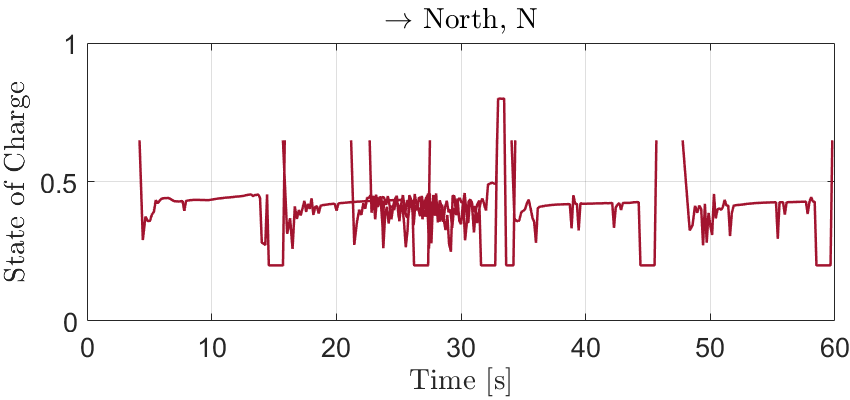

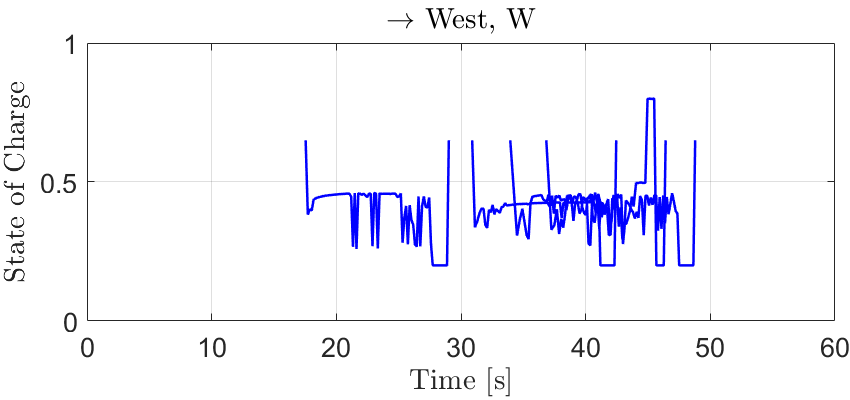

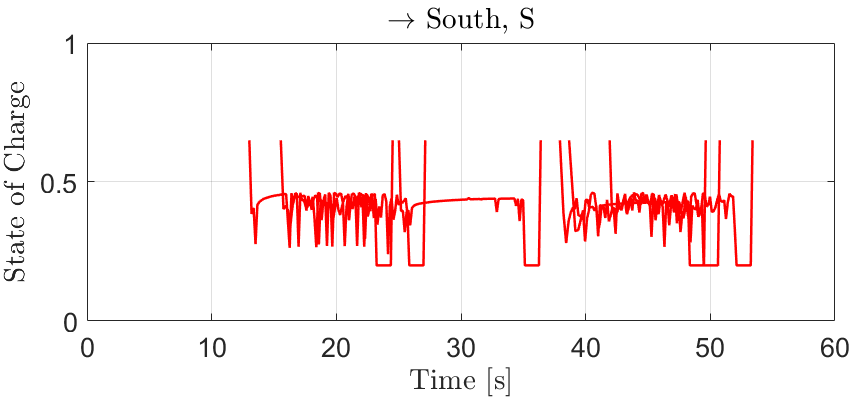

%% Plot SoC
for draw_i = 1:K_sim
    t_draw_i = [];
    SoC_draw_i = [];
    
    figure(6)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 1
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        SoC_draw_i = eval(['SoC_jihe_',num2str(draw_i),';']);        
        plot(t_draw_i,SoC_draw_i,'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,1])
    grid on
    xlabel('Time [s]')
    ylabel('State of Charge')
    set(gca,'fontsize',16)
    title('$\rightarrow$ North, N','interpreter','latex')
    
    
    figure(7)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 2
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        SoC_draw_i = eval(['SoC_jihe_',num2str(draw_i),';']);
        plot(t_draw_i,SoC_draw_i,'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,1])
    grid on
    xlabel('Time [s]')
    ylabel('State of Charge')
    set(gca,'fontsize',16)
    title('$\rightarrow$ West, W','interpreter','latex')
    
    figure(8)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 3
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        SoC_draw_i = eval(['SoC_jihe_',num2str(draw_i),';']);
        plot(t_draw_i,SoC_draw_i,'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,1])
    grid on
    xlabel('Time [s]')
    ylabel('State of Charge')
    set(gca,'fontsize',16)
    title('$\rightarrow$ South, S','interpreter','latex')
    
      
    figure(9)
    x0=200;
    y0=200;
    width=510;
    height=240;
    set(gcf,'units','points','position',[x0,y0,width,height])
    set(0,'defaultTextInterpreter','latex');
    set(gca,'LooseInset',get(gca,'TightInset'))
    if vehicle_direction(draw_i) == 4
        t_draw_i = eval(['t_jihe_',num2str(draw_i),';']);
        SoC_draw_i = eval(['SoC_jihe_',num2str(draw_i),';']);
        plot(t_draw_i,SoC_draw_i,'color',color1(vehicle_direction(draw_i),:),'linewidth',1.5)
        hold on
    end
    xlim([0,t_sim_max])
    ylim([0,1])
    grid on
    xlabel('Time [s]')
    ylabel('State of Charge')
    set(gca,'fontsize',16)
    title('$\rightarrow$ East, E','interpreter','latex')
    
end